# Analyze Full Nash Variety

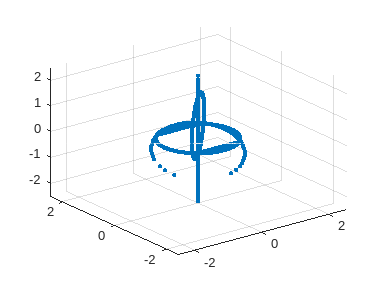

Araw = load("QPDNVexplicit.csv");

x1 = Araw(:, 1);
x2 = Araw(:, 2);
x3 = Araw(:, 3);
x4 = Araw(:, 4);
x5 = Araw(:, 5);
x6 = Araw(:, 6);

Amod1 = [x1, sqrt(x2.^2+x3.^2), x4, sqrt(x5.^2+x6.^2)];
Amod2 = [-x1, -sqrt(x2.^2+x3.^2), -x4, -sqrt(x5.^2+x6.^2)];
% Amod3 = [x1, sqrt(x2.^2+x3.^2), x4, -sqrt(x5.^2+x6.^2)];
% Amod4 = [x1, -sqrt(x2.^2+x3.^2), x4, -sqrt(x5.^2+x6.^2)];

Amod = [x1,x2,x4,x5];

B = StereoProj(Amod);
scatter3(B(:, 1), B(:, 2), B(:, 3), '.')
xlim([-5,5]/2)
ylim([-5,5]/2)
zlim([-5,5]/2)

The hyperoctant picture

phases = [angle(x2+x3*1i), angle(x5+x6*1i)]

phases =     3.1416    3.1416
    3.1416   -0.0000
    3.1416    3.1416
    3.1416         0
    3.1416    3.1416
   -3.1416    0.0000
    3.1416   -3.1416
    3.1416         0
   -3.1416   -3.1416
    3.1416         0


function B = StereoProj(A)
% The input: #(row) datapoints in S^#(col) space embedded in R^(#(col)+1)
B = zeros(size(A, 1), size(A, 2) - 1);
for i = 1:size(B, 2)
    B(:, i) = A(:, i+1)./(1+A(:, 1));
end
end

function A = InvStereoProj(B)
A = zeros(size(B, 1) + 1, size(B, 2));
R2 = sum(B.^2, 2);
for i = 1:size(B, 1)
    A(:, i+1) = 2*B(:, i)./(1+R2);
end
A(:, 1) = (1-R2)./(1+R2);
end